# Simulación paramétrica de una membrana rectangular

`Haţiegan, C., Gillich, G. R., Răduca, E., Nedeloni, M. D., & Cîndea, L. (2013). Equation of Motion and Determining the Vibration Mode Shapes of a Rectangular Thin Plate Simply Supported on Contour Using MATLAB. ``Analele Universitatii'Eftimie Murgu'``, ``20``(1).`	Disponible en [ResearhGate](https://www.researchgate.net/publication/260243971_Equation_of_Motion_and_Determining_the_Vibration_Mode_Shapes_of_a_Rectangular_Thin_Plate_Simply_Supported_on_Contour_Using_MATLAB)	

`Resumen`

`Este artículo presenta la ecuación biharmónica diferencial de placas delgadas  de las cuales se obtuvieron las formas del modo de vibración para una placa delgada rectangular simplemente apoyada en el contorno. Además, se obtuvieron los primeros cuatro modos de vibración y las primeras cuatro frecuencias naturales de esta delgada placa rectangular de acero. Usando el software MATLAB, las formas del modo de vibración se representaron gráficamente.`

% inicialiacion
clear variables; clc;
% Dimensiones del rectangulo
a = 1;              % 1000 mm 
b = 0.5;            % 500 mm
%h = 1.698/1000;     % 1.698 mm

% Parametros del acero
Rho = 7850;         % Kg/m^2
v   = 0.3;          % Coeficiente de Poisson adimencional
E   = 2.1 * 10^11;  % N/m^2

## Calculo de h

En el articulo no indica el valor, se deduce numericamente del modo de vibracion 

w_11 = 149.607.

h = 149.607 / ((5*pi^2)*sqrt(E/(12*(1-v)*Rho)))

h = 0.0017

## Cálculo de la rigidez D

## 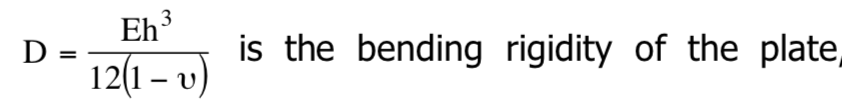

D = (E*h^3)/(12*(1-v))

D = 122.5691

## Frecuencias angulares  [rad/s]

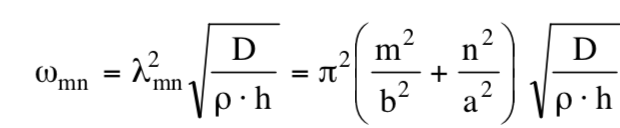

% Modos de vibración
m = 1:4;
n = 1:4;

w_11 = (pi^2)*((m(1)^2./b^2)+(n(1)^2./a^2))*sqrt(D/(Rho*h))

w_11 = 149.6070


w_ij = zeros(length(m),length(n));
for i=1:length(m)
    for j=1:length(n)
        w_ij(i,j) = (pi^2)*((m(i).^2./b^2)+(n(j).^2./a^2))*sqrt(D/(Rho*h));
    end
end
w_ij

w_ij = 	1.0e+03 *

    0.1496    0.2394    0.3890    0.5984
    0.5087    0.5984    0.7480    0.9575
    1.1071    1.1969    1.3465    1.5559
    1.9449    2.0347    2.1843    2.3937


## Modos de vibracion

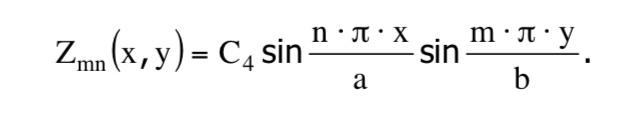

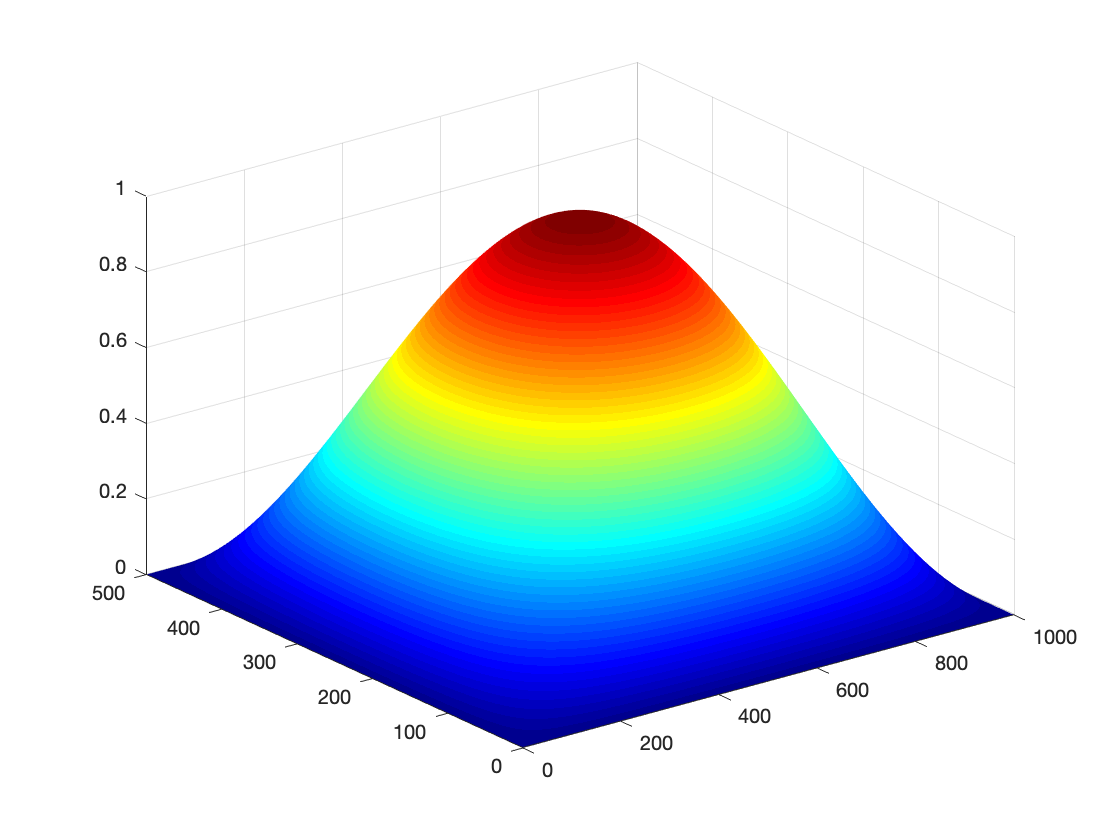

C_4     = 1;        % Esta normalizado
dx      = 0.005;    % Paso recomendado por el autor
dy      = 0.005;
x = 0:dx:a;
y = 0:dy:b;
[X,Y] = meshgrid(x,y);
figure(1)
title('Vibration mode shapes, with n=1 and m=1')
 Z_11 = C_4 .* sin((1.*pi/a).*X) .* sin((1*pi/b).*Y);
 surf(1000.*X,1000.*Y,Z_11)
 colormap("jet")
 shading interp;

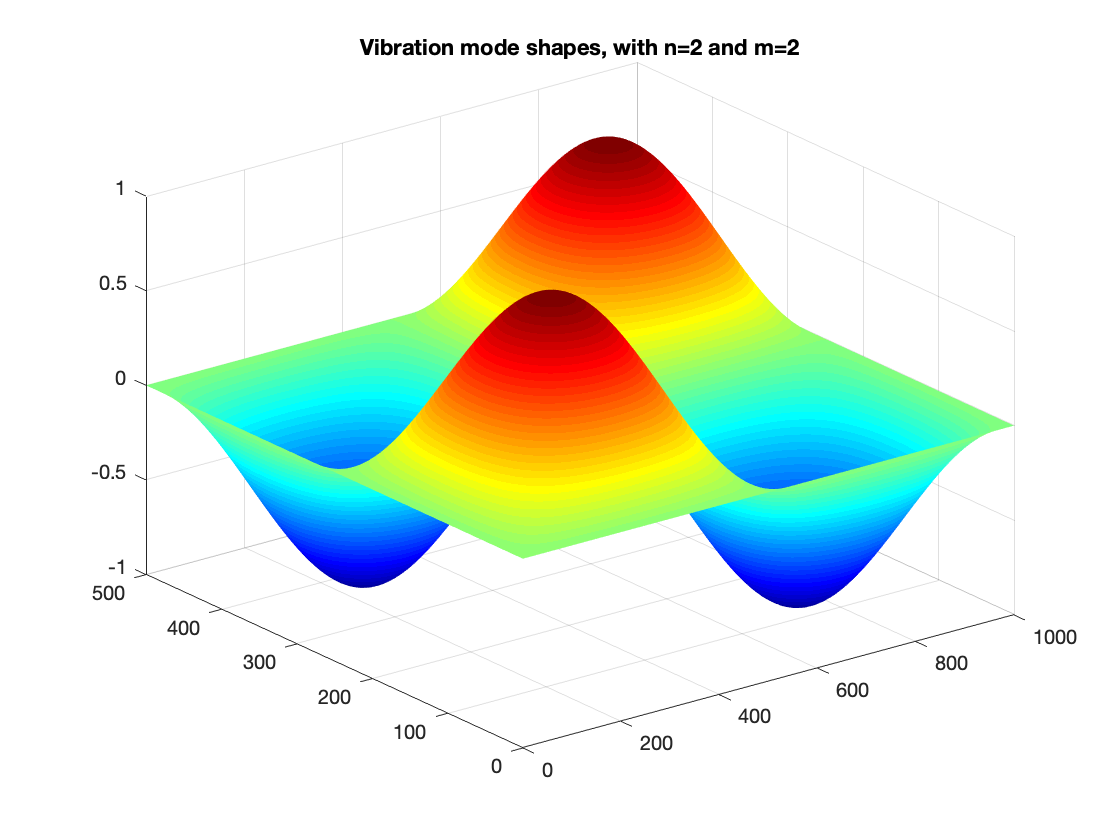

figure(2)
title('Vibration mode shapes, with n=2 and m=2')

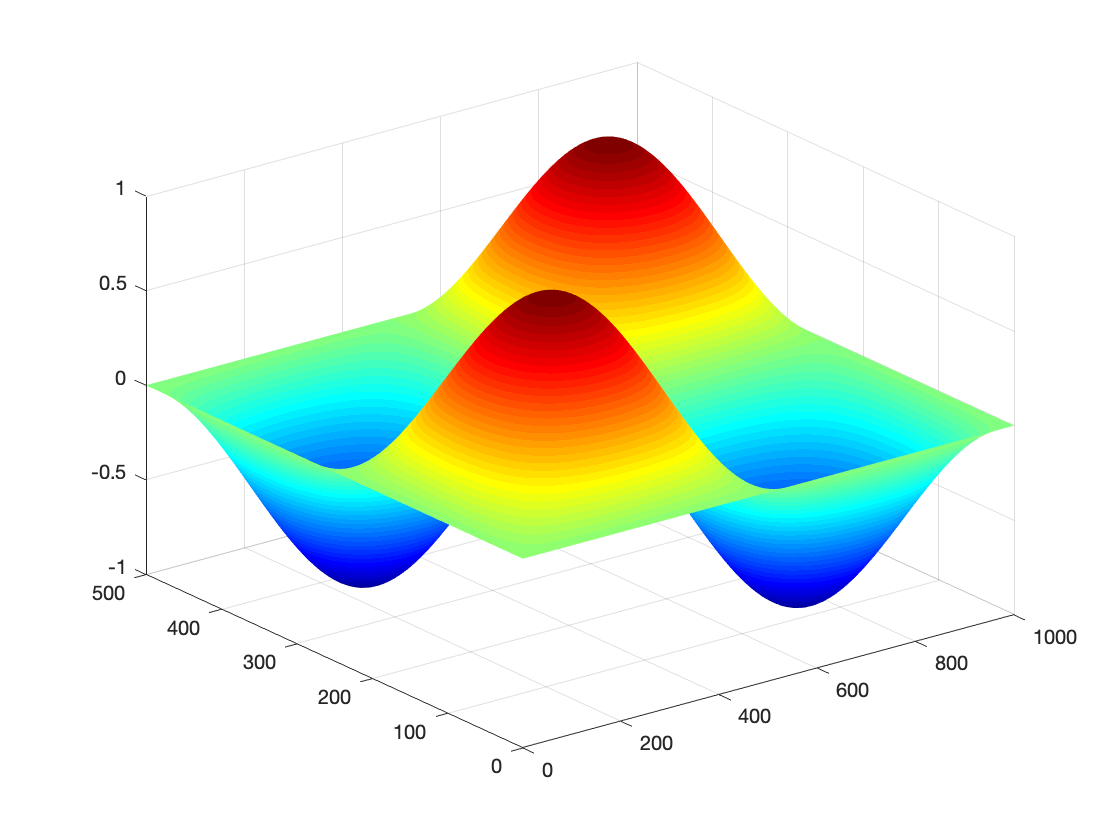

Z_22 = C_4 .* sin((2.*pi/a).*X) .* sin((2*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_22)
colormap("jet")
shading interp;

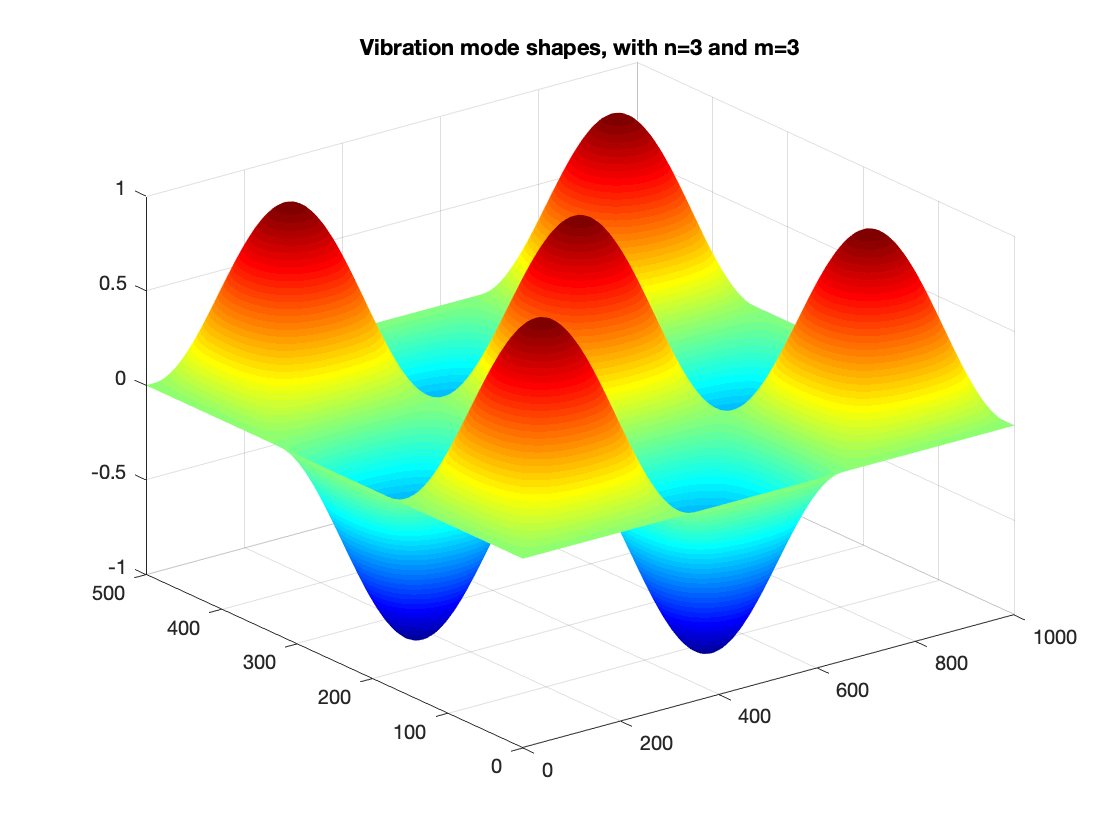

figure(3)
title('Vibration mode shapes, with n=3 and m=3')

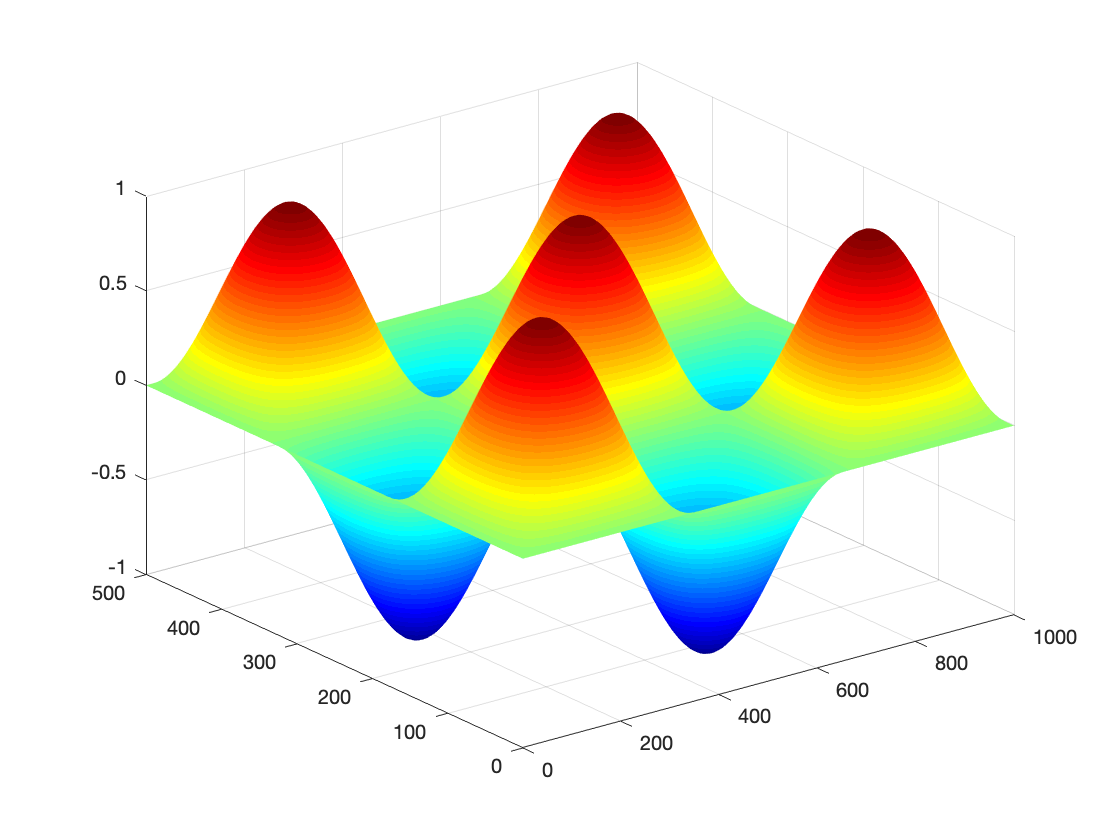

Z_33 = C_4 .* sin((3.*pi/a).*X) .* sin((3*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_33)
colormap("jet")
shading interp;

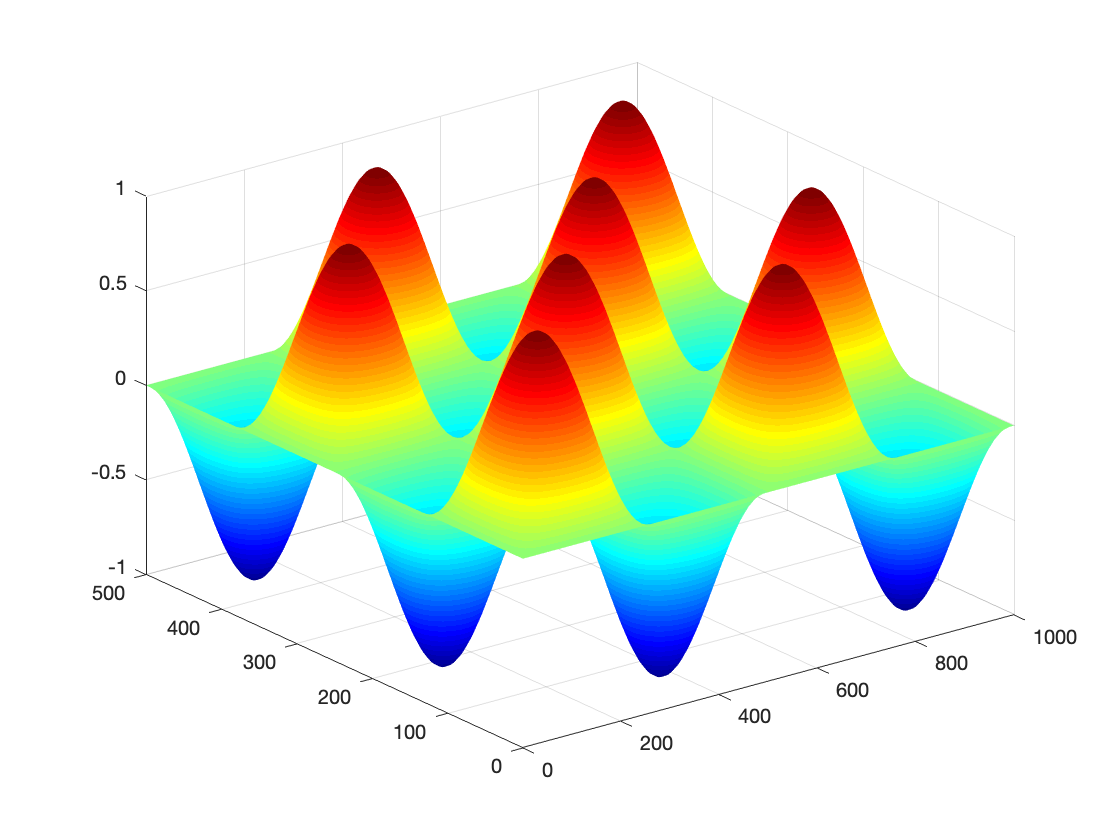

figure(4)
title('Vibration mode shapes, with n=4 and m=4')
Z_44 = C_4 .* sin((4.*pi/a).*X) .* sin((4*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_44)
colormap("jet")
shading interp;

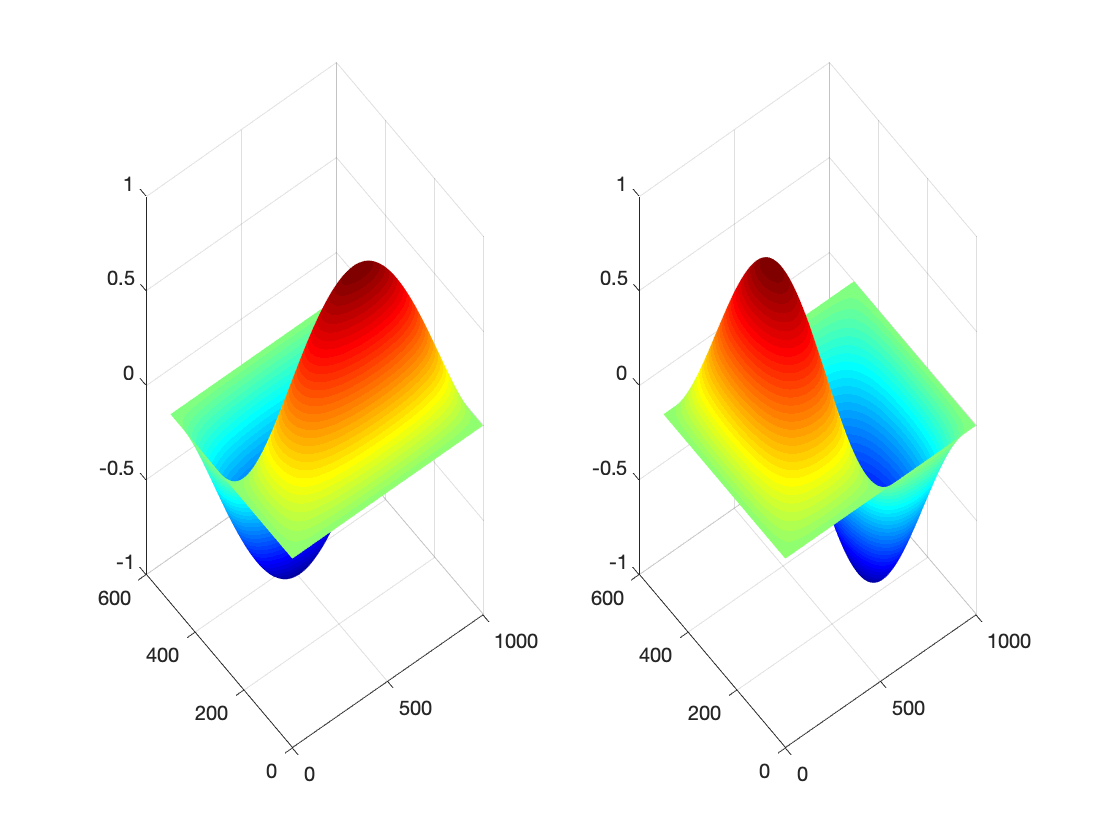

figure(5)
title('Vibration mode shapes, with n=1 and m=2')
Z_12 = C_4 .* sin((1.*pi/a).*X) .* sin((2*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_12)
colormap("jet")
shading interp;

figure(6)
title('Vibration mode shapes, with n=2 and m=1')
Z_21 = C_4 .* sin((2.*pi/a).*X) .* sin((1*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_21)
colormap("jet")
shading interp;

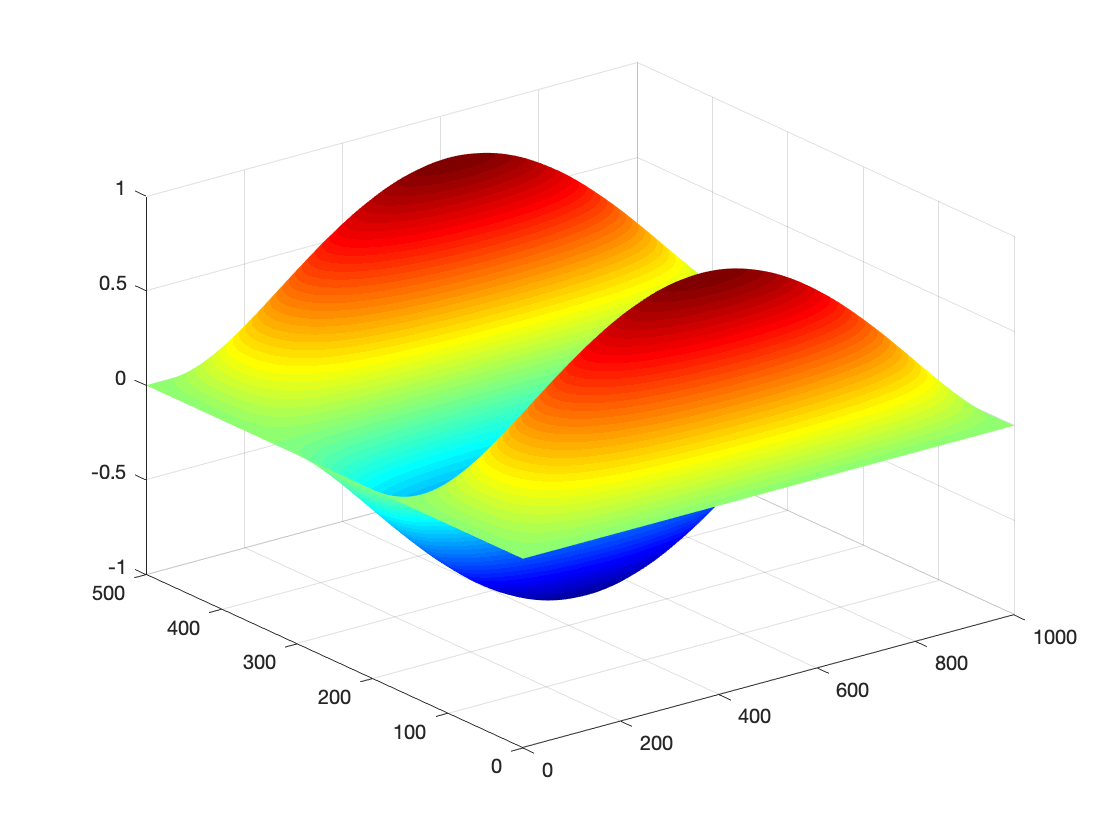

figure(7)
title('Vibration mode shapes, with n=1 and m=3')
Z_13 = C_4 .* sin((1.*pi/a).*X) .* sin((3*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_13)
colormap("jet")
shading interp;

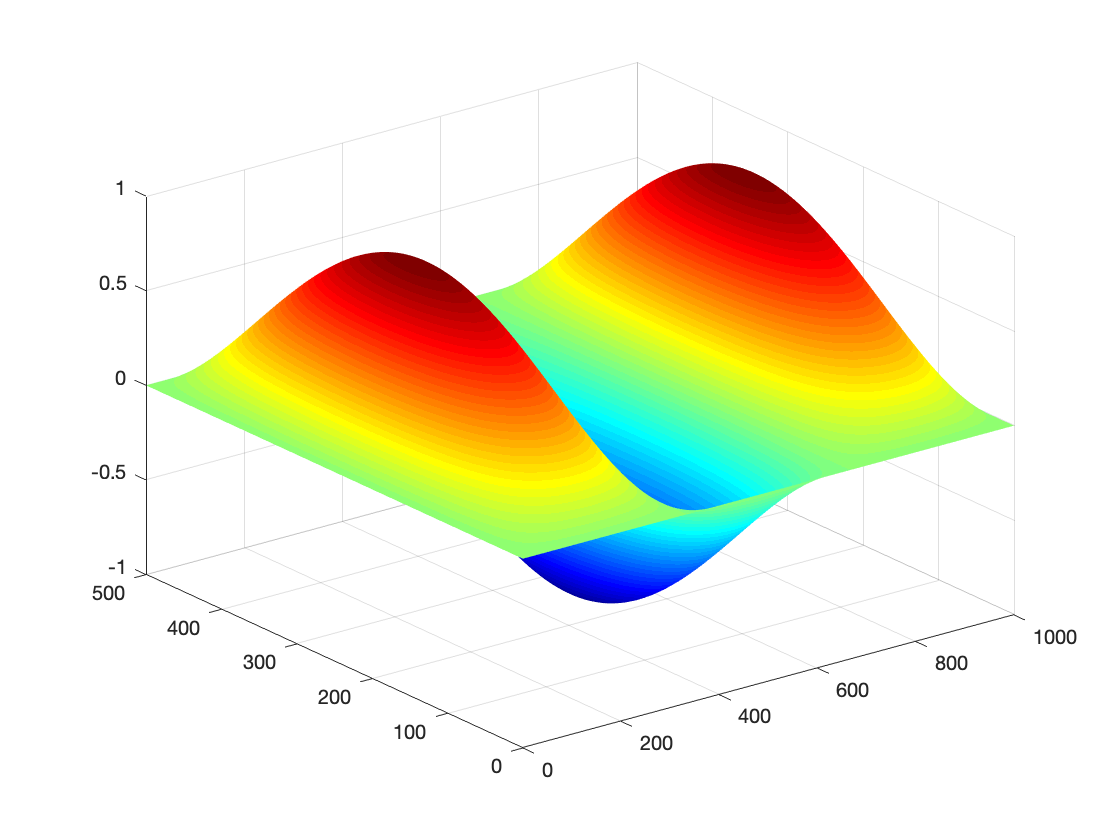


figure(8)
title('Vibration mode shapes, with n=3 and m=1')
Z_31 = C_4 .* sin((3.*pi/a).*X) .* sin((1*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_31)
colormap("jet")
shading interp;

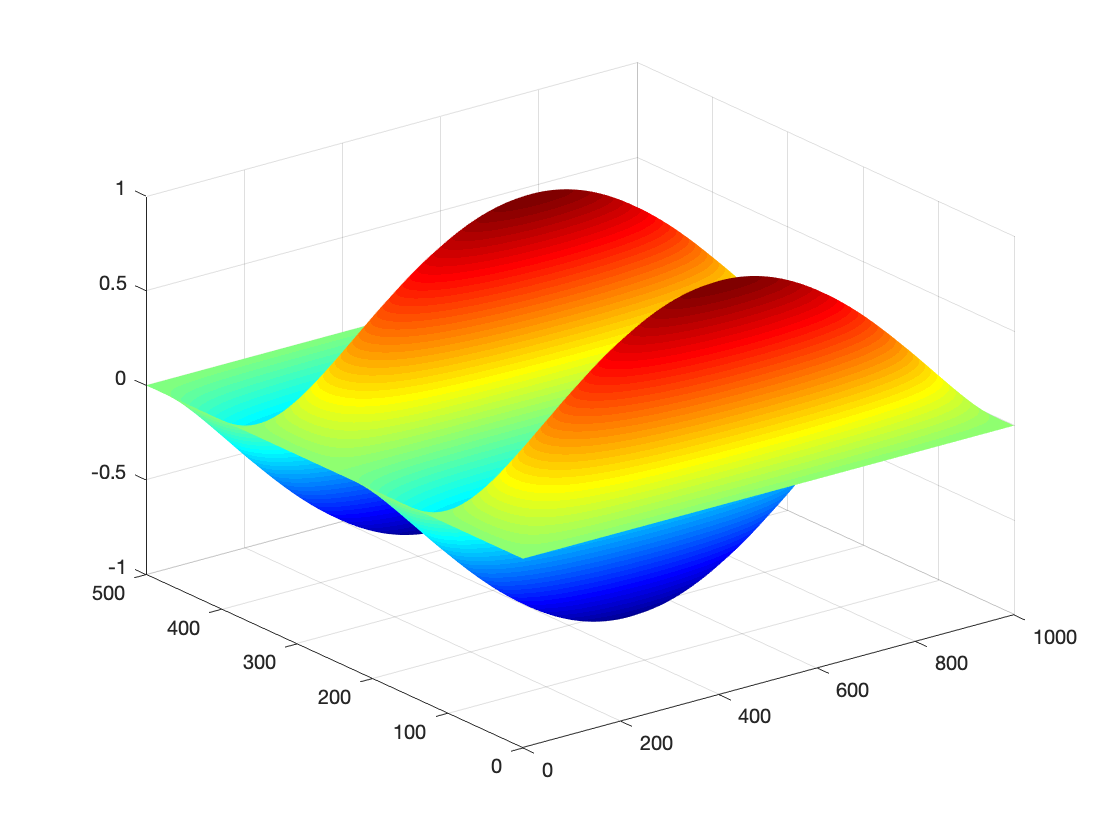

figure(9)
title('Vibration mode shapes, with n=1 and m=4')
Z_14 = C_4 .* sin((1.*pi/a).*X) .* sin((4*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_14)
colormap("jet")
shading interp;

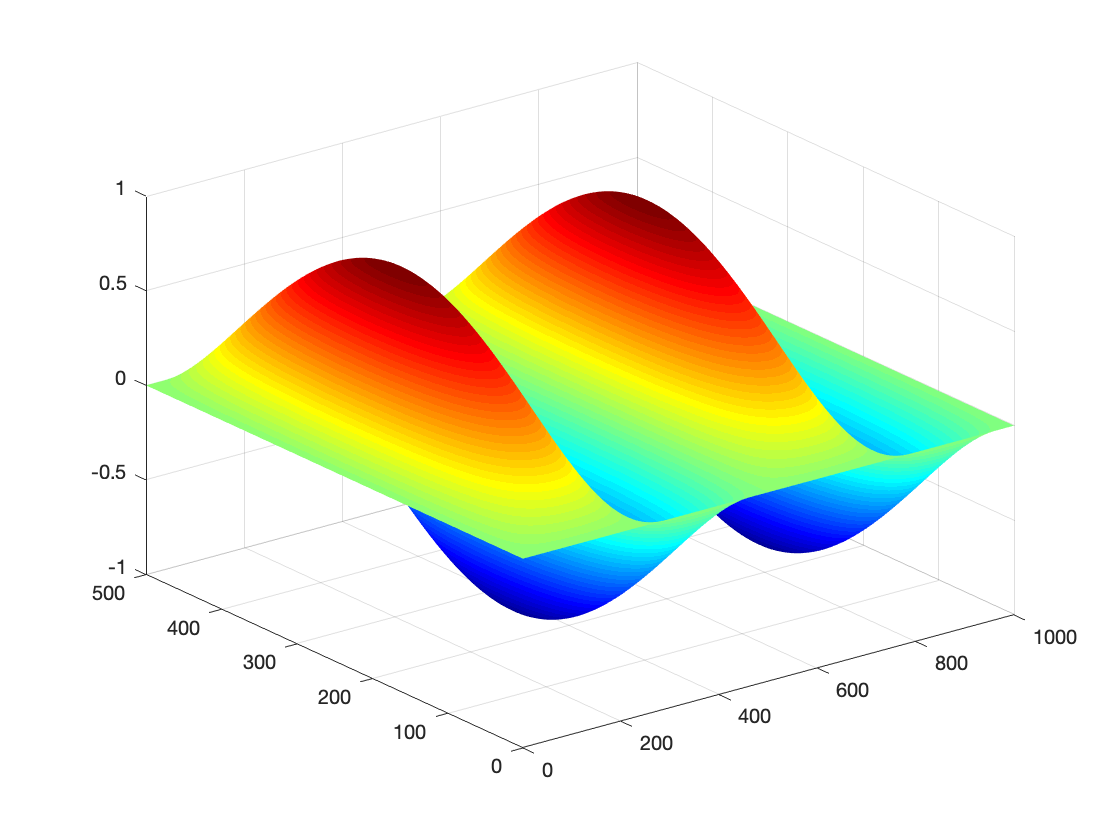


figure(10)
title('Vibration mode shapes, with n=4 and m=1')
Z_41 = C_4 .* sin((4.*pi/a).*X) .* sin((1*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_41)
colormap("jet")
shading interp;

figure(11)
title('Vibration mode shapes, with n=2 and m=3')
Z_23 = C_4 .* sin((2.*pi/a).*X) .* sin((2*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_23)
colormap("jet")
shading interp;

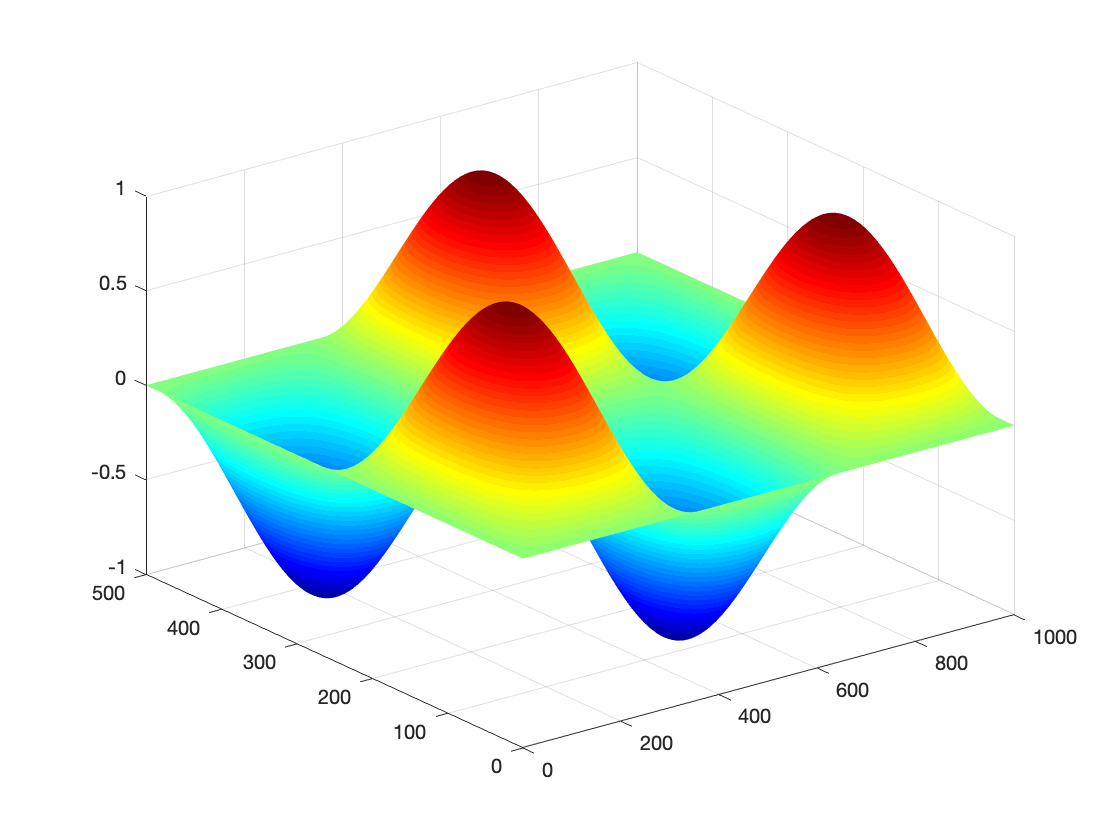


figure(12)
title('Vibration mode shapes, with n=3 and m=2')
Z_32 = C_4 .* sin((3.*pi/a).*X) .* sin((2*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_32)
colormap("jet")
shading interp;

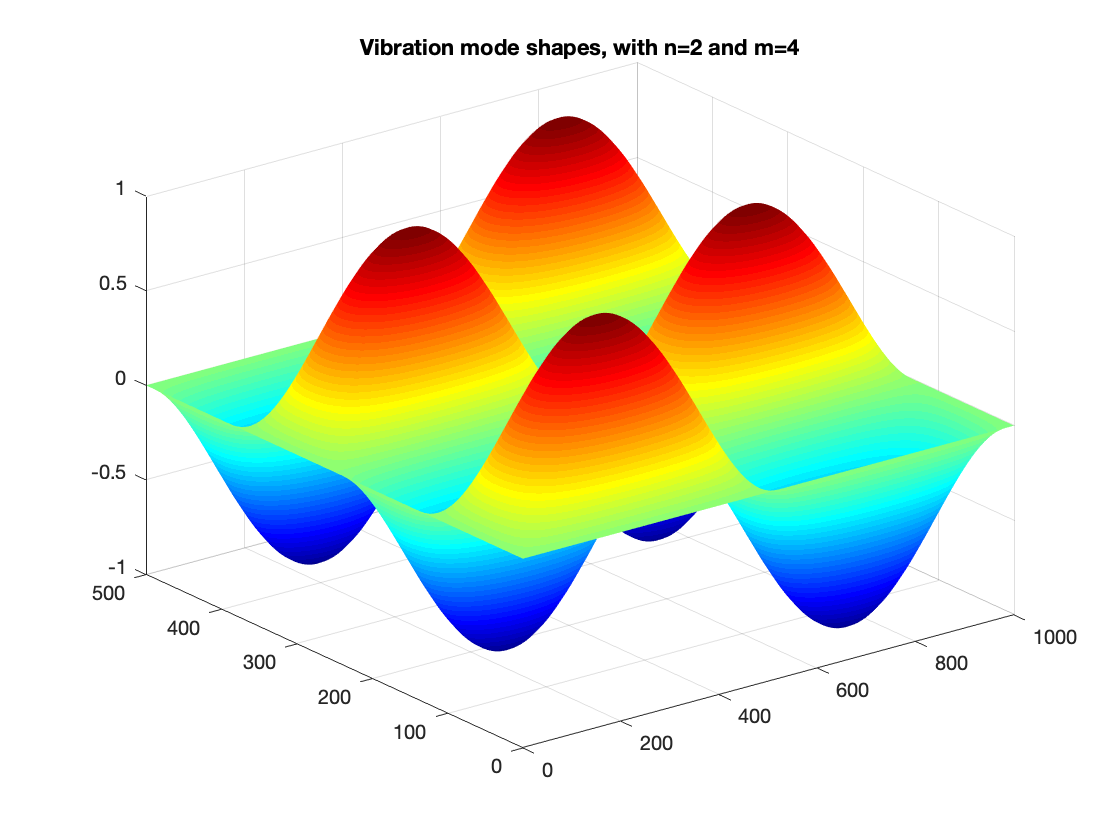

figure(13)
title('Vibration mode shapes, with n=2 and m=4')

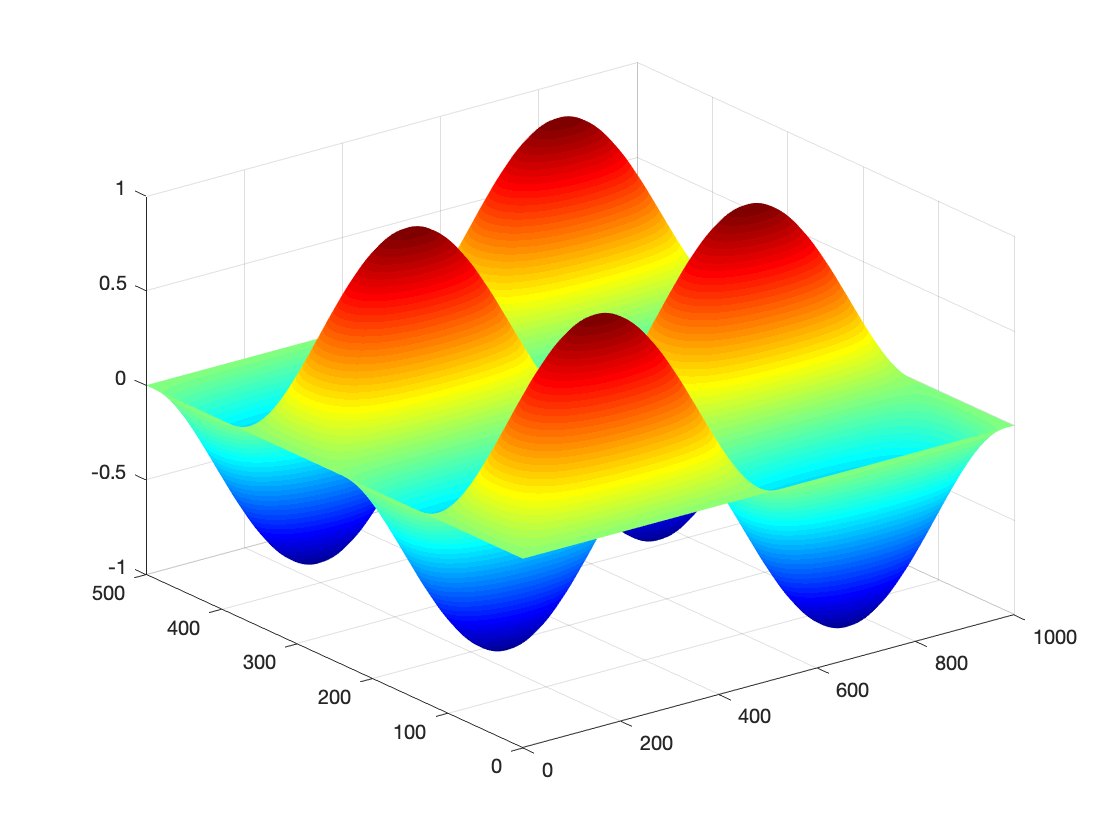

Z_24 = C_4 .* sin((2.*pi/a).*X) .* sin((4*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_24)
colormap("jet")
shading interp;

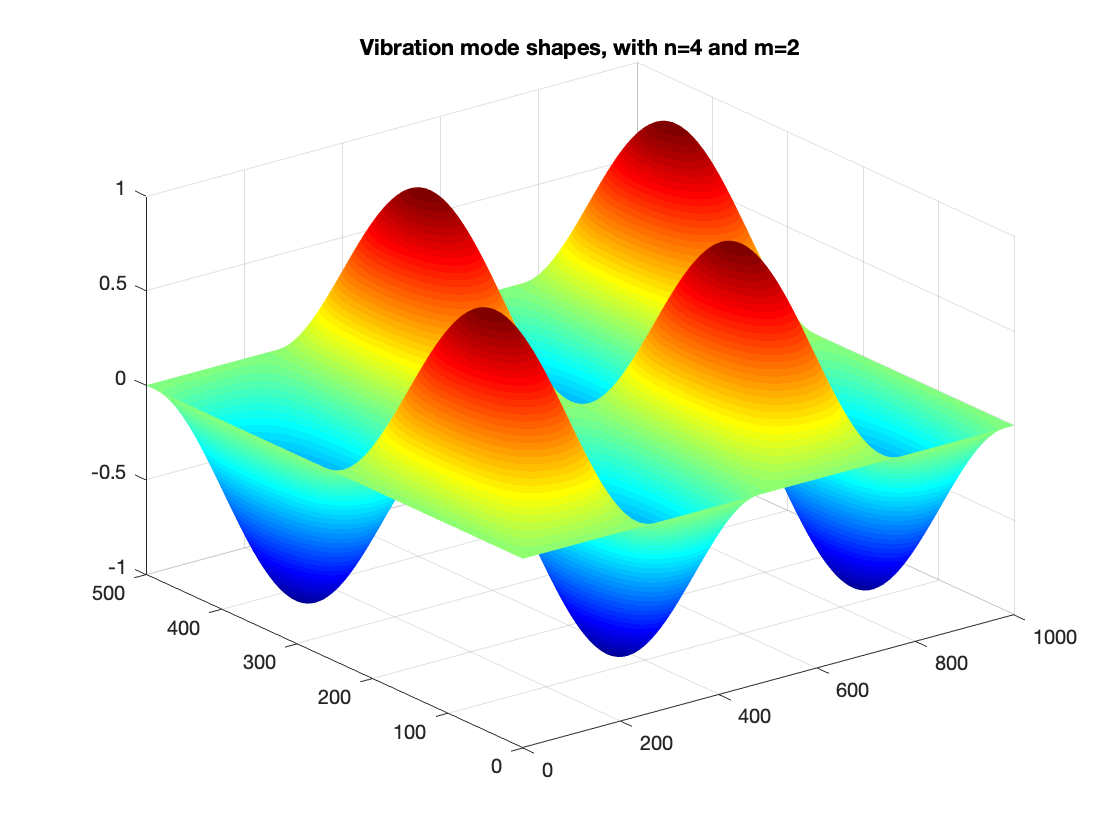


figure(14)
title('Vibration mode shapes, with n=4 and m=2')

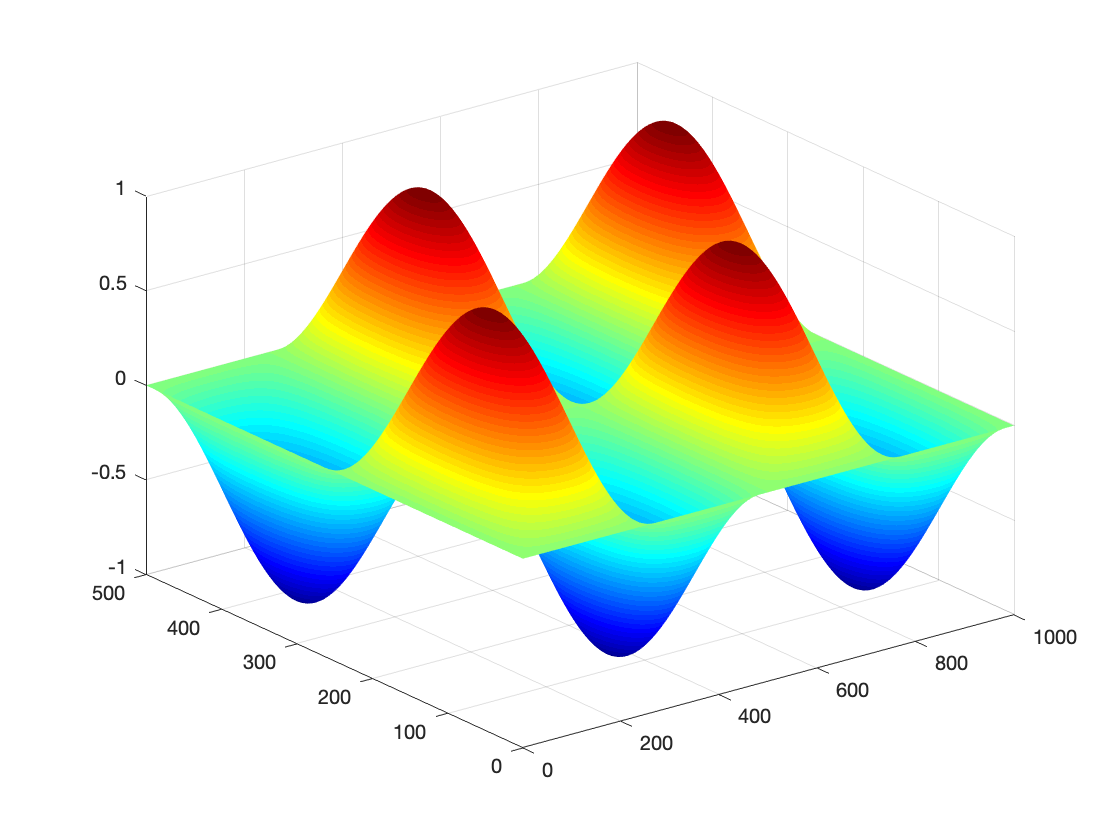

Z_42 = C_4 .* sin((4.*pi/a).*X) .* sin((2*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_42)
colormap("jet")
shading interp;

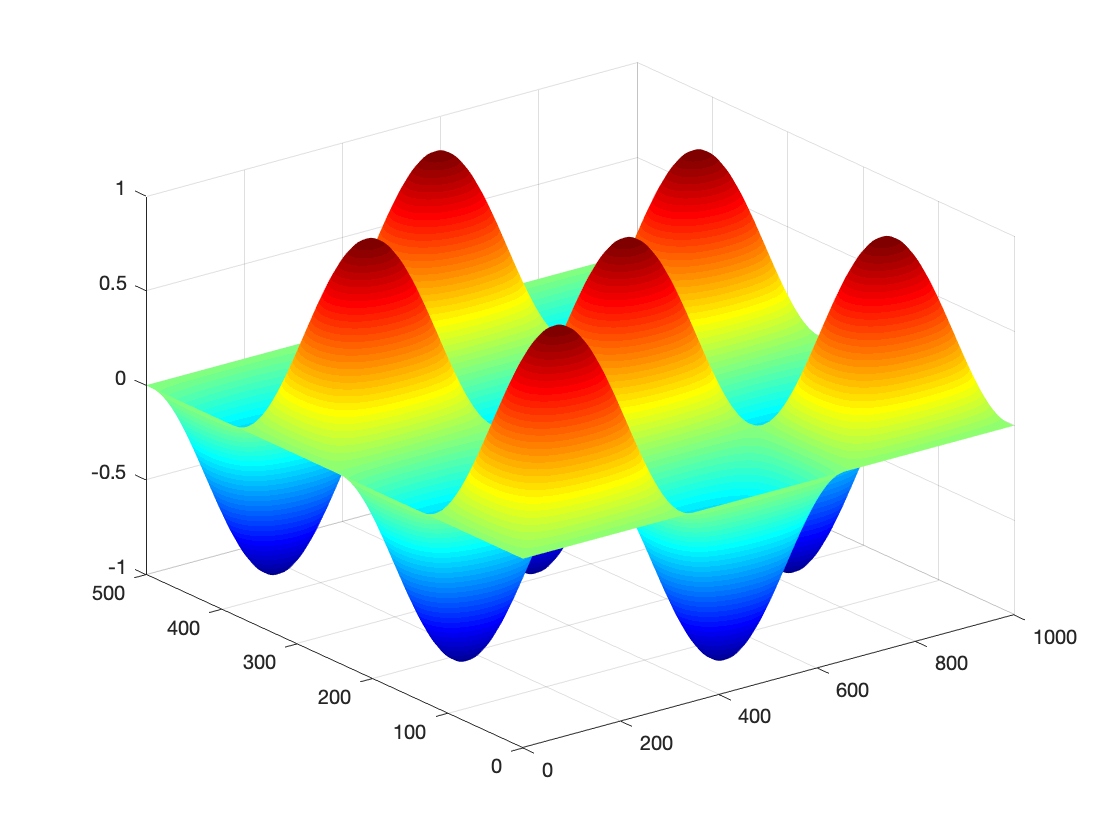

figure(15)
title('Vibration mode shapes, with n=3 and m=4')
Z_34 = C_4 .* sin((3.*pi/a).*X) .* sin((4*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_34)
colormap("jet")
shading interp;

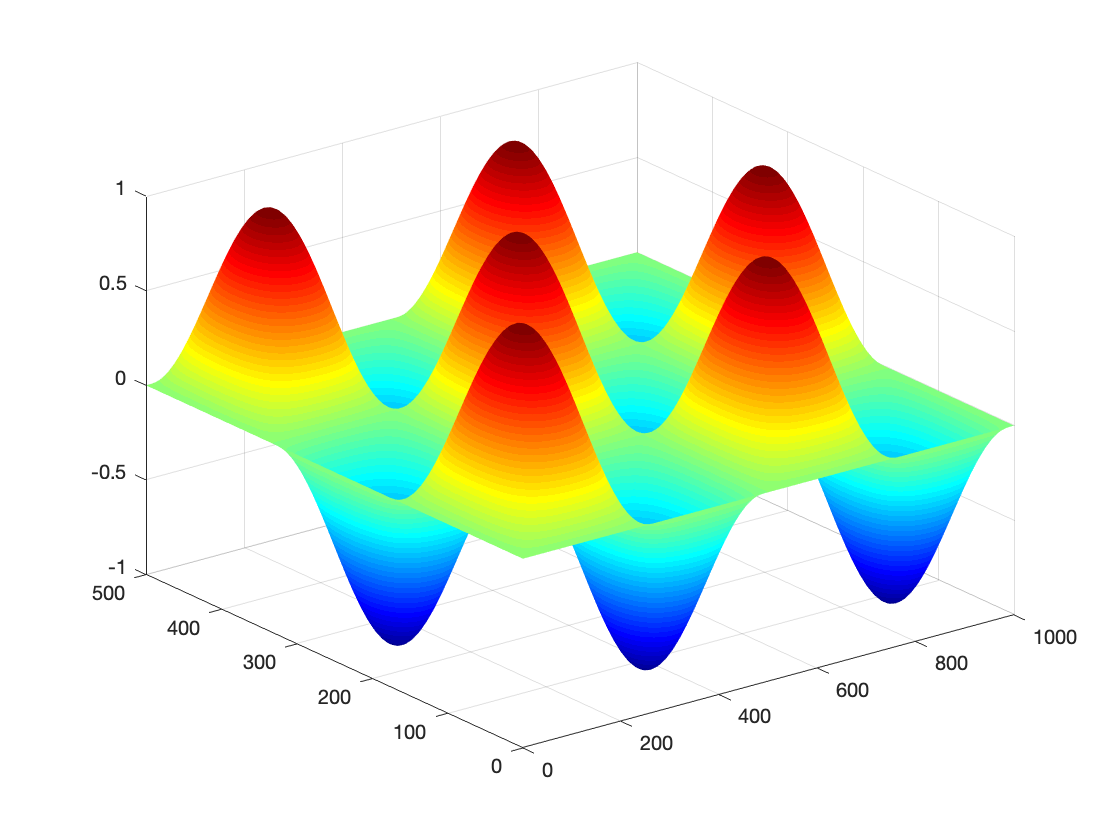


figure(16)
title('Vibration mode shapes, with n=4 and m=3')
Z_43 = C_4 .* sin((4.*pi/a).*X) .* sin((3*pi/b).*Y);
surf(1000.*X,1000.*Y,Z_43)
colormap("jet")
shading interp;

% Este codigo no funciona, error Matrix dimensions must agree
%
% Z_mn = zeros(length(x), length(y));
% 
% for i=1:length(m)
%     for j=1:length(n)
%         Z_mn(i,j) = C_4 .* sin((n.*pi/a).*X) .* sin((m*pi/b).*Y);
%     end
% end
%Z_mn
